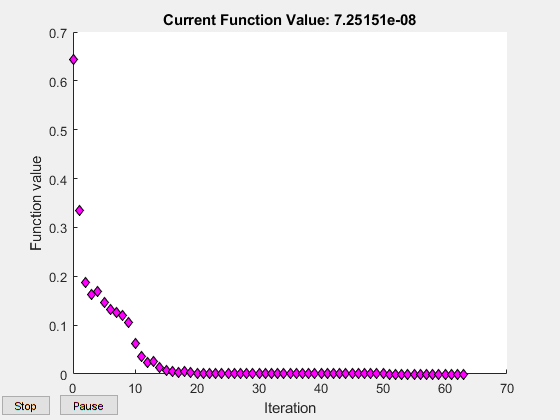


Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.



%Run the simulation over double support. Find the starting and ending
%points. Generate a curve that connects them in swing phase.
clear all
path(pathdef)
addpath(genpath('Experiments'))
addpath(genpath('Analysis'))
addpath(genpath('UtilityFunctions'))
addpath('Model')
addpath(genpath('Model\SimulationFunctions'))

global flowdata

flowdata = flowData;

flowdata.E_func = @MechE_func;

%Ode equation handle and tolerenaces
flowdata.eqnhandle = @dynamics;
flowdata.odeoptions = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);

%Flags
flowdata.Flags.silent = false;
flowdata.Flags.ignore = true;

%Simulation parameters
flowdata.Parameters.Environment.slope = 0;   %ground slope
flowdata.Parameters.dim = 16;        %state variable dimension

%Biped Parameters
flowdata.Parameters.Biped = load('MassInertiaGeometry.mat');
load('MassInertiaGeometry.mat');
%lf = 0.225
%la = 0.1;
lt = 0.5;
ls = 0.5;
flowdata.Parameters.Biped.asvec = [Mt Ms Mh Mf lt ls lf la Itz Ity Itx Isz Isx Isy Ihz Ihx Ihy];
params = flowdata.Parameters.Biped.asvec ;
%Trajectory
load('slip_walk.mat') 
pf1 = out_extra.steps{1}.phases{2}.foot_pos_1;
pf2 = out_extra.steps{1}.phases{2}.foot_pos_2;
indexi = find(tout==out_extra.steps{1}.phases{2}.tstart,1);
indexf = find(tout==out_extra.steps{1}.phases{2}.tend,1);
zs_dsupp = xout(indexi,:);
zf_dsupp = xout(indexf,:);

%fmincon Optimization to solve inverse kinematic problem at the end of SLIP
%Double Support (mapping SLIP cords into Flat Foot Biped cords)
dim = flowdata.Parameters.dim;
A=[];
b=[];

%Constrain stance heel to ground
Aeq = zeros(4,16);
Aeq(1,1) = 1;
Aeq(2,2) = 1;
Aeq(3,9) = 1;
Aeq(4,10) = 1;
beq = [pf1(1);pf1(2);0;0];
load('xi.mat')
%load('xi_slip_dsupp.mat')
x0 = xi;
x0(1)=pf1(1);
x0(2)=pf1(2);
x0(7) = deg2rad(-5);

%Bounded the joints to be +- 90 degree rotation from initial condition
lb = x0 - [pi/2*ones(1,8),inf(1,8)];
ub = x0 + [pi/2*ones(1,8),inf(1,8)];
lb(1:2)=-inf;
lb(3) = 0;
ub(6) = 0;
ub(7) = x0(7)-1e-3;
ub(1:2)= inf;

options = optimoptions('fmincon','MaxFunctionEvaluations',10000,'OptimalityTolerance',1e-15,'Display','final-detailed','PlotFcn','optimplotfval');
cost_fun = @(x)IK_SLIP_pos_cost(x,zs_dsupp,pf2);
con_fun = @(x)IK_SLIP_pos_con(x,zs_dsupp,pf2);
[xs_dsupp1,fval] = fmincon(cost_fun,x0,A,b,Aeq,beq,lb,ub,[] ,options);

play_handels_messiah

%find velocities
dim = flowdata.Parameters.dim;
A=[];
b=[];
%xs_dsupp1(9:16)=0;
%Use pos optimzation result as constraint and initial guess
Aeq = [eye(8,8),zeros(8,8);zeros(2,16)];
Aeq(9,9)=1;
Aeq(10,10) = 1;
beq = xs_dsupp1(1:10);
xs_dsupp1(9:16)=0;
lb = [];
ub = [];

f = @(v)IK_SLIP_vel_eq([xs_dsupp1(1:10),v],zs_dsupp)

f = function_handle with value:
    @(v)IK_SLIP_vel_eq([xs_dsupp1(1:10),v],zs_dsupp)


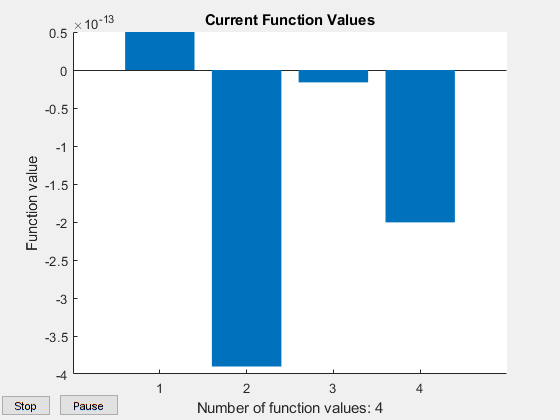


Equation solved. The sum of squared function values, r = 1.951518e-25, is less
than sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of
r, 7.194682e-15, is less than 1e-4*options.OptimalityTolerance = 1.000000e-10.



v0 = zeros(1,6);
v0(1) = -pi;
v0(2)= -pi;
% cost_fun = @(x)IK_SLIP_vel_cost(x,zs_dsupp,1);
% [xs_dsupp2,fval] = fmincon(cost_fun,xs_dsupp1,A,b,Aeq,beq,lb,ub,[],options);
% 
% cost_fun = @(x)IK_SLIP_vel_cost(x,zs_dsupp,2);
% [xs_dsupp3,favl] = fmincon(cost_fun,xs_dsupp2,A,b,Aeq,beq,lb,ub,[],options);
options = optimoptions('fsolve','Display','final-detailed','PlotFcn','optimplotfval','MaxFunctionEvaluations',100000,'MaxIterations',4e3);
v_star = fsolve(f,v0,options);

xs_dsupp3 = [xs_dsupp1(1:10),v_star];
play_handels_messiah

xi_slip_dsupp=xs_dsupp3;
dir_path = pwd;
save(strcat(dir_path,'\Experiments\InvKinOpt\xi_slip_dsupp.mat'),'xi_slip_dsupp');

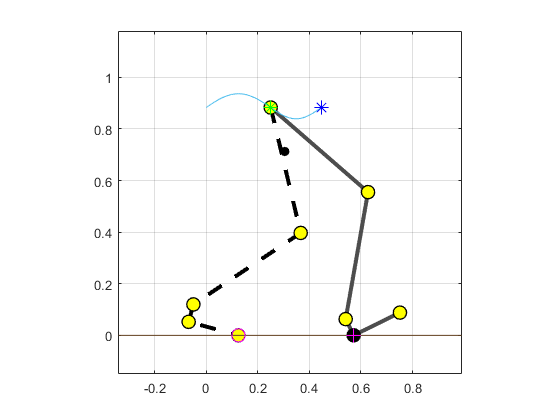

%plot results
figure;
draw7Link(xs_dsupp3','na');

hold on
plot(xout(:,1),xout(:,2))
plot(zs_dsupp(1),zs_dsupp(2),'g*','MarkerSize',10)
plot(zf_dsupp(1),zf_dsupp(2),'b*','MarkerSize',10)
plot(pf1(1),pf1(2),'m+','MarkerSize',10)
plot(pf2(1),pf2(2),'mo','MarkerSize',10)

xlim([-0.34 0.99])
ylim([-0.15 1.18])

draw7Link(xi_slip_dsupp','na');

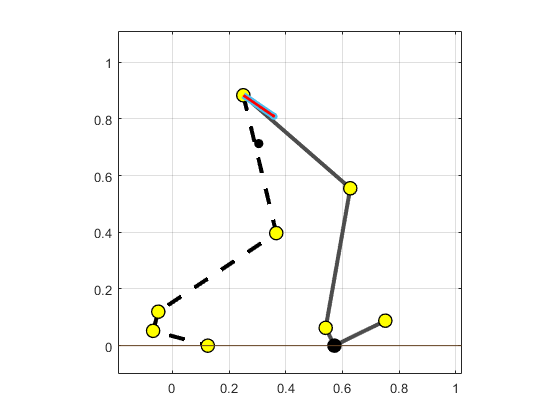


quiver(zs_dsupp(1),zs_dsupp(2),zs_dsupp(3),zs_dsupp(4), 1/10,'LineWidth',5)

hip_vel= Hip_vel_func(xi_slip_dsupp',params);
hip_vel = hip_vel(1:2,4);

quiver(zs_dsupp(1),zs_dsupp(2),hip_vel(1),hip_vel(2), 1/10,'LineWidth',2,'Color','r')

toe_p_vel= Toe_Sw_vel_func(xi_slip_dsupp',params);
toe_vel = toe_p_vel(1:2,4);

toe_sw_pose = Toe_Sw_pos_func(xi_slip_dsupp',params);
toe_xy = toe_sw_pose(1:2,4);

quiver(toe_xy(1),toe_xy(2),toe_vel(1),toe_vel(2), 1/10,'LineWidth',2,'Color','r')

xlim([-0.19 1.02])
ylim([-0.10 1.11])
hold off